## 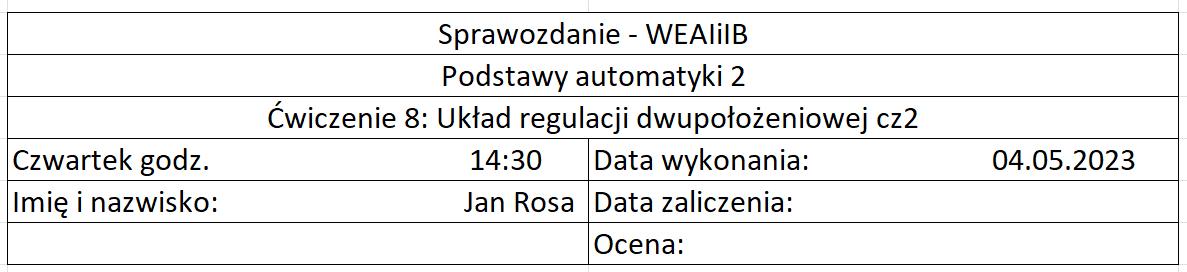

## Wstęp

Celem niniejszego sprawozdania jest zbadanie stabilności układu regulacji z liniowym obiektem i nieliniowym regulatorem statycznym. W zadaniu został przedstawiony zamknięty układ regulacji z liniowym obiektem oraz regulatorem 2-położeniowym bez histerezy i z histerezą. W ramach zadania należy sprawdzić, dla jakiej wartości amplitudy przekaźnika ym oraz histerezy równej h = 0.0, h = 0.05, h = 0.1, amplituda cyklu granicznego będzie większa od 1, 2, 5. W ramach opracowania wyników należy przedstawić rysunek z przebiegiem wielkości regulowanej w układzie oraz narysować wykres Nyquista części liniowej wraz z wykresem krytycznym. Porównanie wyników analitycznych z otrzymanymi podczas laboratorium będzie dodatkową analizą.

h = 0

y = 7.3000

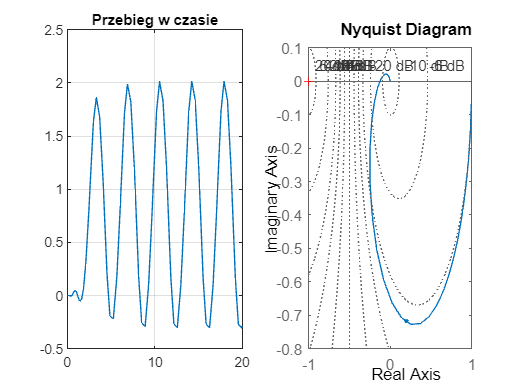

h = 0

y = 13

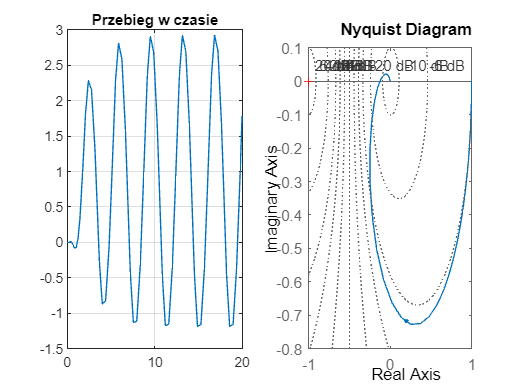

h = 0

y = 33

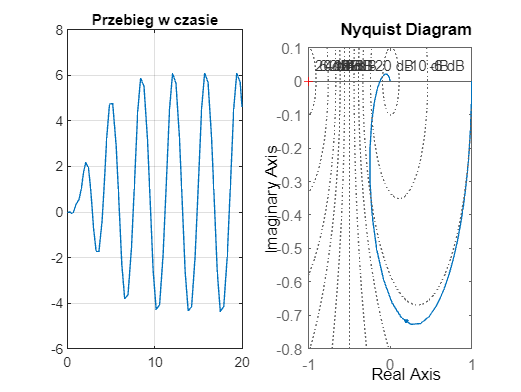

h = 0.0500

y = 6

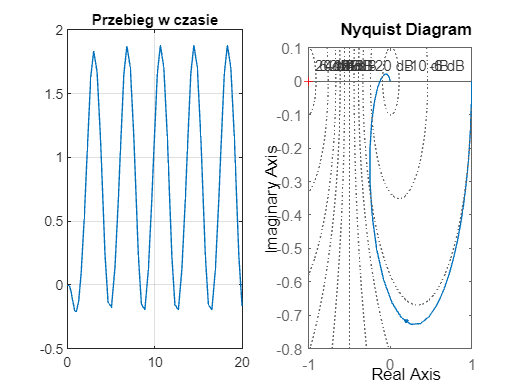

h = 0.0500

y = 12

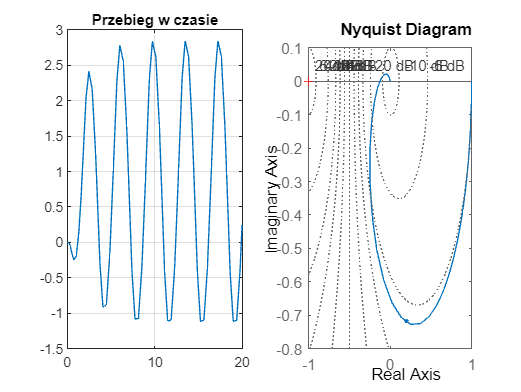

h = 0.0500

y = 32

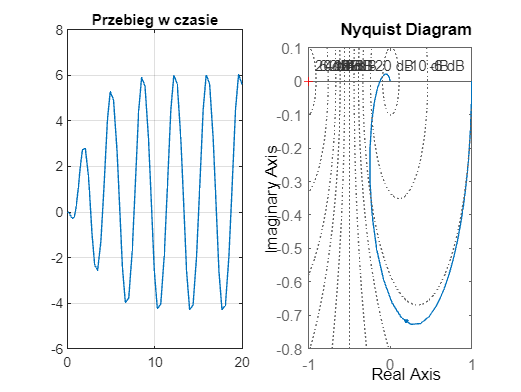

h = 0.1000

y = 5

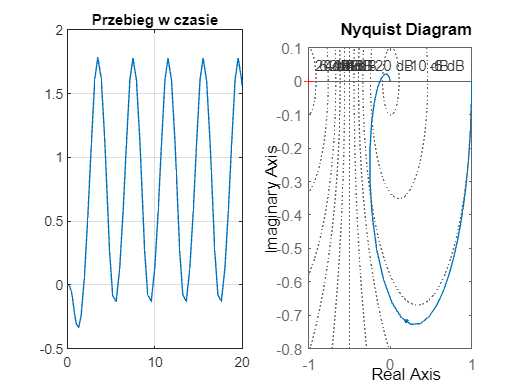

h = 0.1000

y = 12

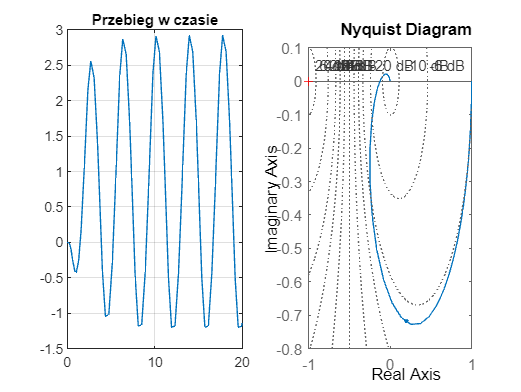

h = 0.1000

y = 31

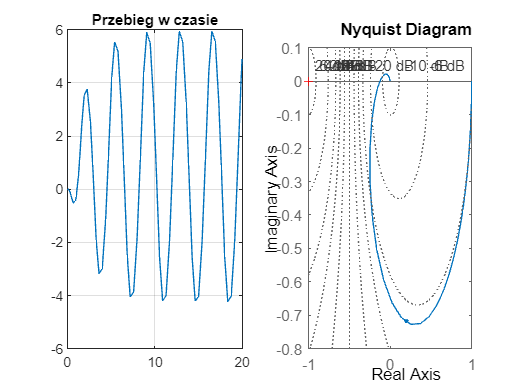

G = [1, 3, 3, 1];
h_vec = [0, 0.05, 0.1];
y_mat = [[  7.3, 13, 33];
         [  6, 12, 32];
         [  5, 12, 31]];
y = 10;
for i = 1:3
    for j = 1:3
        h = h_vec(i);
        y = y_mat(i, j);
        test(G, h, y);
    end
end

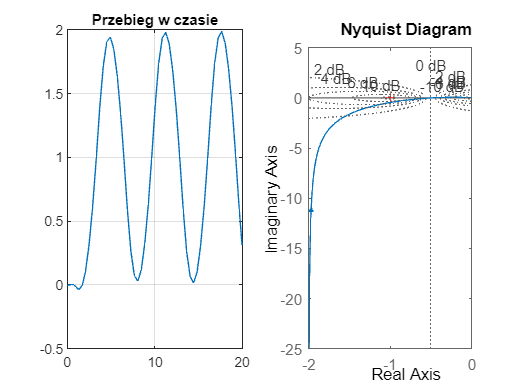

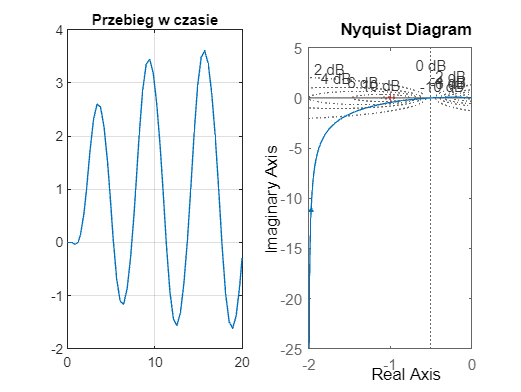

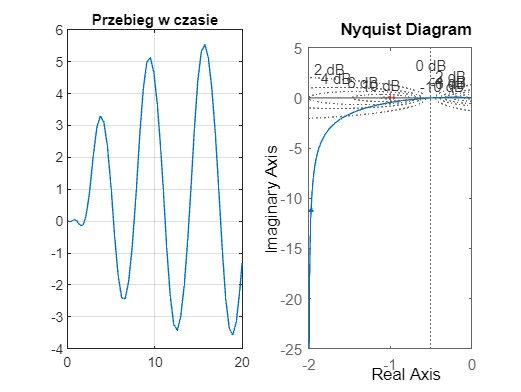

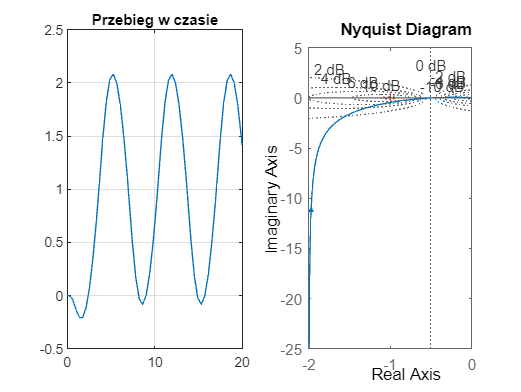

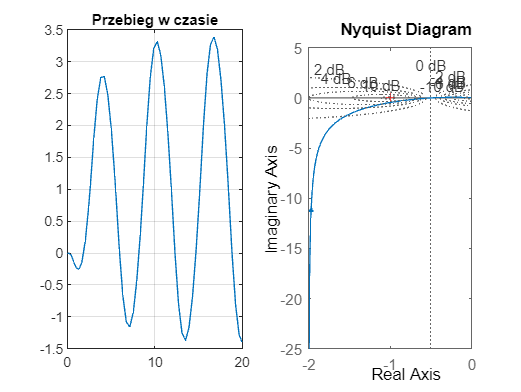

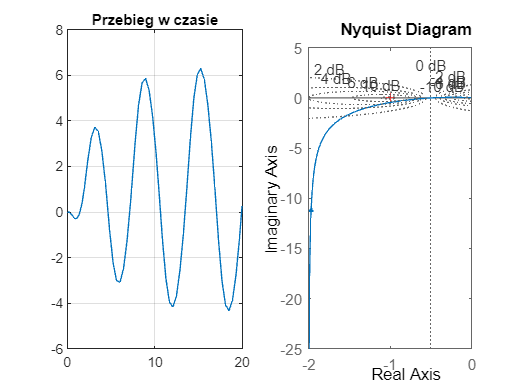

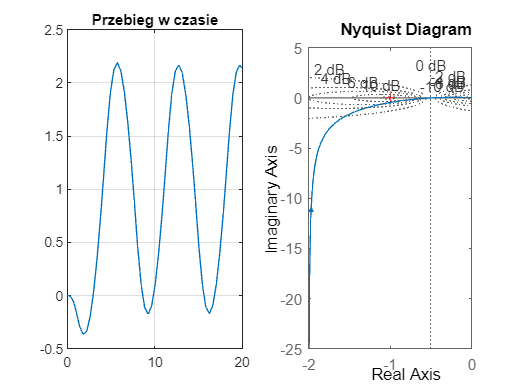

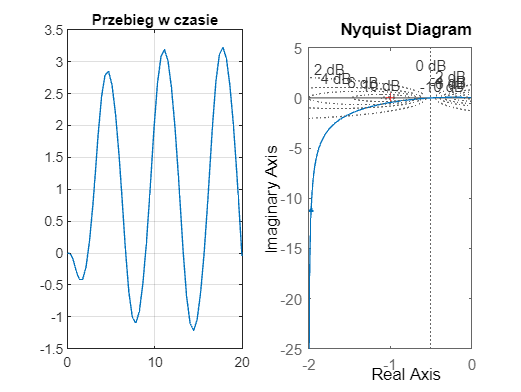

G = [1, 2, 1, 0];
y_mat = [[  1.5, 4, 7];
         [  1.5, 3.5, 8];
         [  1.5, 3.1, 7.3]];
y = 10;
for i = 1:3
    for j = 1:3
        h = h_vec(i);
        y = y_mat(i, j);
        test(G, h, y);
    end
end

h = 0

y = 80

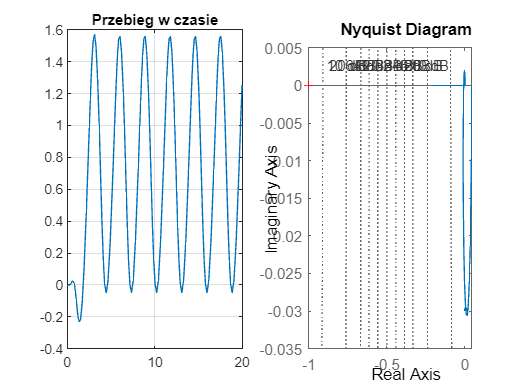

h = 0

y = 200

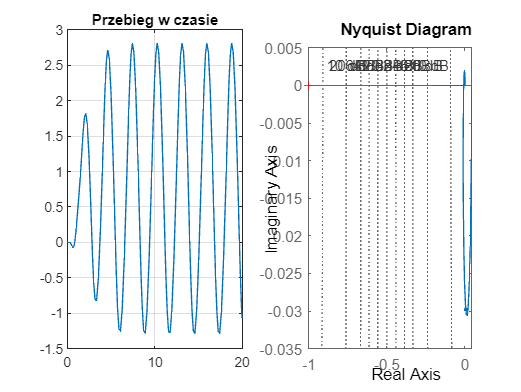

h = 0

y = 500

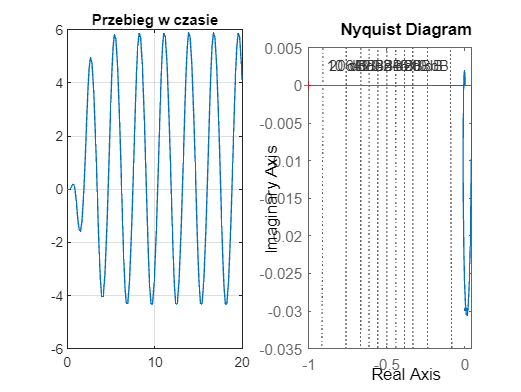

h = 0.0500

y = 100

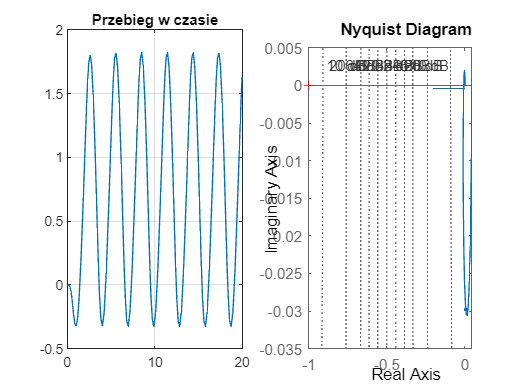

h = 0.0500

y = 250

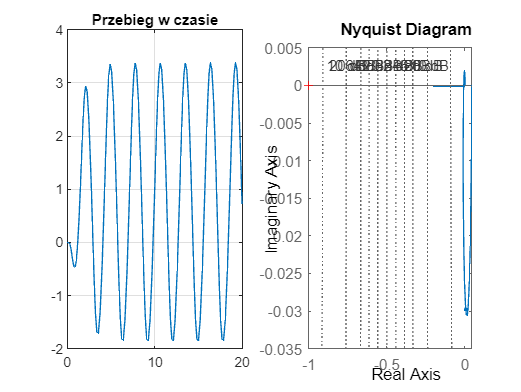

h = 0.0500

y = 420

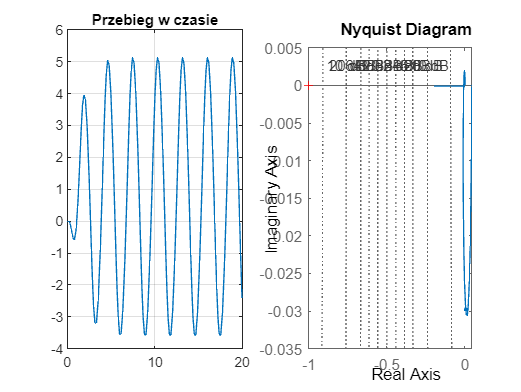

h = 0.1000

y = 110

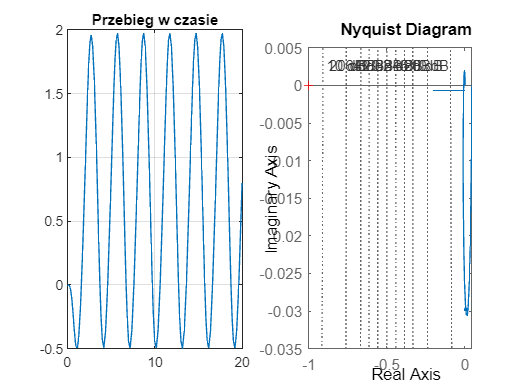

h = 0.1000

y = 222

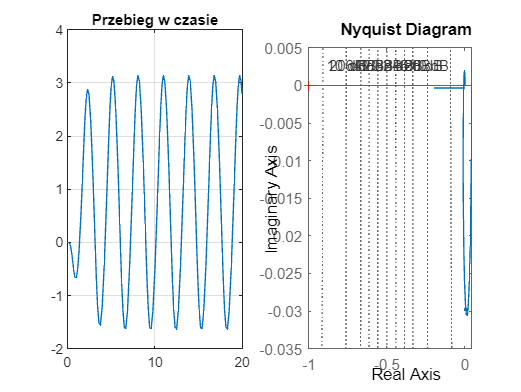

h = 0.1000

y = 450

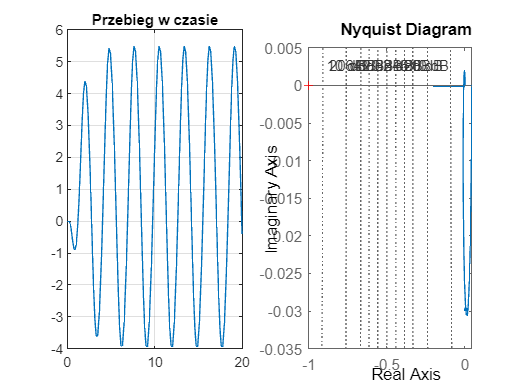

G = [1, 10, 35, 50, 24];
y_mat = [[  80, 200, 500];
         [  100, 250, 420];
         [  110, 222, 450]];
y = 10;
for i = 1:3
    for j = 1:3
        h = h_vec(i);
        y = y_mat(i, j);
        test(G, h, y);
    end
end

function [] = test(G, h, ym)
    obiekt = tf([0,0,0,1], G);
    c = (-pi*h)/(4 * ym);
    out = sim("obiekt_reg.slx");
    figure;
    subplot(1, 2, 1);
    plot(out.ScopeData.time, out.ScopeData.signals.values);
    title("Przebieg w czasie");
    grid on;
    subplot(1, 2, 2);
    n = nyquistplot(obiekt);
    opt = getoptions(n);
    opt.ShowFullContour = 'off';
    setoptions(n, opt);
    hold on;
    plot([-0.2, 0], [c, c]);
    grid on;
    hold off;
end